### 初始化

clc;
clear

### 参数设置

M = 70000;
Fs = 10E6;
% pathname = 'Data\Instrument_Capture_2023_761k_2.csv';
pathname = 'FilterAfter.csv';

### 数据读取

wave_data = readmatrix(pathname);
vout = wave_data(1:M,1) - wave_data(1:M,2);

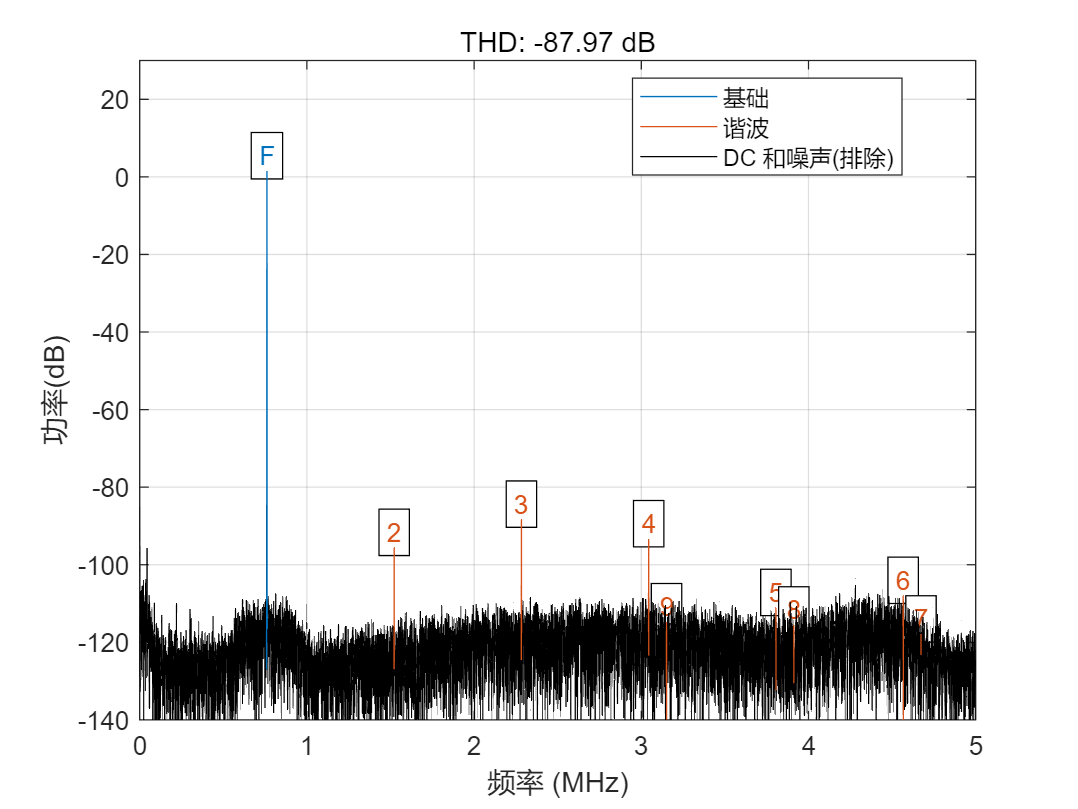

ans = -87.9689

thd(vout, Fs, 9, 'aliased')

[r,harmpow,harmfreq] = thd(vout, Fs, 9, 'aliased')

r = -87.9689

harmpow =     1.4562
  -95.6506
  -88.3728
  -93.4198
 -111.1205
 -104.7710
 -117.9738
 -115.3206
 -113.2159


harmfreq = 	1.0e+06 *

    0.7610
    1.5220
    2.2830
    3.0440
    3.8050
    4.5662
    4.6729
    3.9121
    3.1507


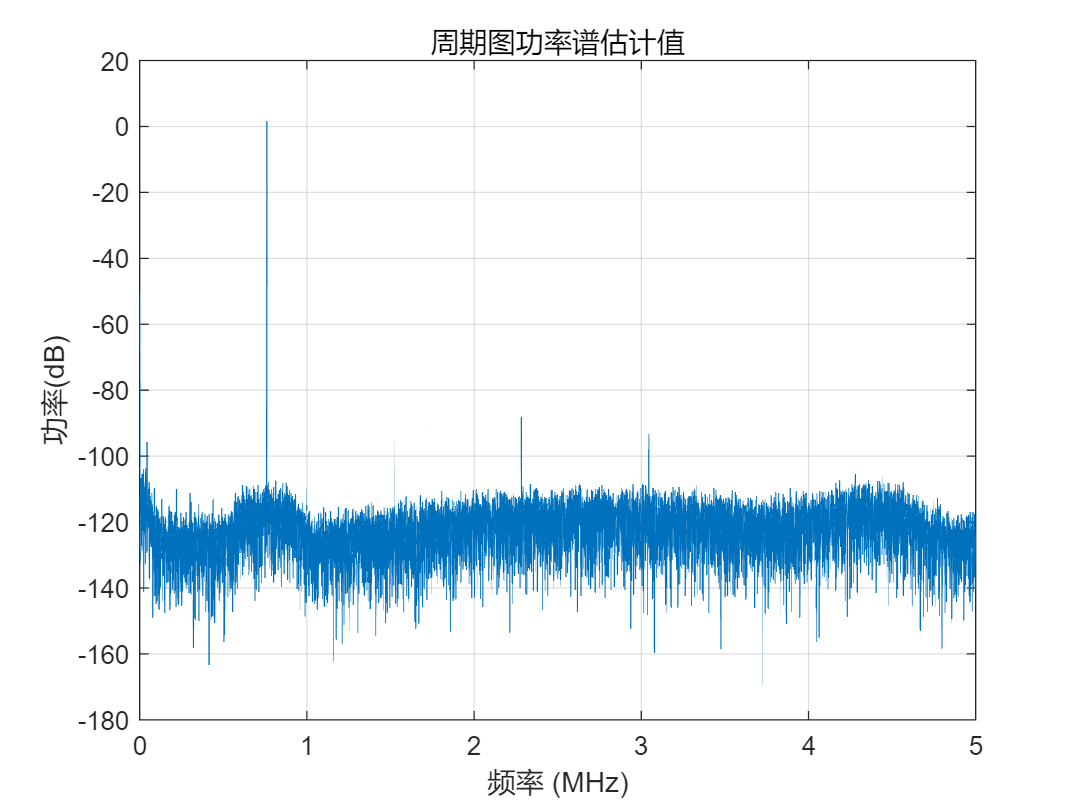

periodogram(vout, kaiser(M,38), M, Fs, "onesided", "power")

## 数据Auto-Recording

- 写入模式 -w+

- 可变数据长度

- 默认数据为2为小数点

- 格式最好是xls, csv也可以

Time = datetime('now', 'InputFormat','dd-MMM-uuuu HH:mm:ss');
Frequency = harmfreq(1);
Amplitude = max(vout) - min(vout);
THD = r;
% HD = num2cell(harmpow(1:3))';
t = table(Time,string(pathname),Frequency,Amplitude,THD, harmpow(1), harmpow(2), harmpow(3),...
    'VariableNames',{'Time', 'File', 'Frequency', 'Amplitude', ...
    'THD','HD1', 'HD2', 'HD3'})

t = 1×8 table
           Time                  File           Frequency    Amplitude      THD       HD1        HD2        HD3  
    ___________________    _________________    _________    _________    _______    ______    _______    _______

    2023-04-04 09:28:23    "FilterAfter.csv"    7.61e+05      3.3452      -87.969    1.4562    -95.651    -88.373


% write_context = {Time pathname Frequency Amplitude THD}
write_context = [write_context HD]

write_context = 1×23 cell 数组
    {[2023-04-04 09:16:56]}    {'FilterAfter.csv'}    {[7.6100e+05]}    {[3.3452]}    {[-87.9689]}    {[1.4562]}    {[-95.6506]}    {[-88.3728]}    {[1.4562]}    {[-95.6506]}    {[-88.3728]}    {[1.4562]}    {[-95.6506]}    {[-88.3728]}    {[1.4562]}    {[-95.6506]}    {[-88.3728]}    {[1.4562]}    {[-95.6506]}    {[-88.3728]}    {[1.4562]}    {[-95.6506]}    {[-88.3728]}


% writecell(write_context, 'Recording.xlsx', 'Sheet', 'Sheet1', 'WriteMode', 'append')
writetable(t, 'Recording.xlsx', 'Sheet', 'Sheet1', 'WriteMode', 'append')

ans = datetime
   2023-04-04 08:58:47
